# **PRACTICE 7. F1-SCORE**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# EXERCISE 1: F1-SCORE

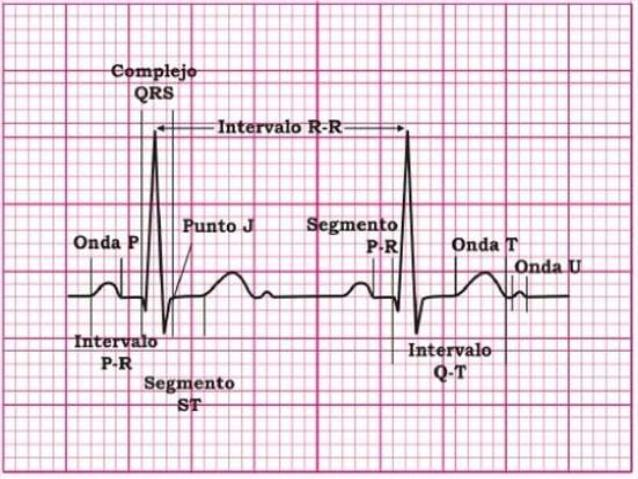

Using the global practice database '**Cardiac Recognition Systems**', perform the following actions:

a). Load the data contained in the file 'mitbih_train.csv' and create two variables. One variable called 'x_tr' will contain all the data from the first 187 columns and will represent the pattern of characteristics of each individual. The next variable called 'y_tr' will contain all the data from the last column, indicating the type of arrhythmia. (See global practice statement). 

Perform the same action for the file 'mitbih_test.csv' and create the variables x_ts and y_ts.

data = csvread ('mitbih_train.csv');
test = csvread ('mitbih_test.csv');
x_tr=data(:,1:187)';
y_tr=data(:,188)';
x_ts=test(:,1:187)';
y_ts=test(:,188)';
%clearvars data test;

b). To reduce computation time, shuffle the data and select the first half of the total characteristics from x_tr and x_ts variables.

[x_tr, y_tr] = shuffle(x_tr, y_tr);
[x_ts, y_ts] = shuffle(x_ts, y_ts);

n_variables = ceil(size(x_tr,1)/2);
x_tr_half = x_tr(1:n_variables,:)';
x_ts_half = x_ts(1:n_variables,:)';
y_tr=y_tr';
y_ts=y_ts';

% i will proceed with the better half of the characteristics
[~,X,~,~,explained] = pca([x_tr x_ts]'); %!!!Matlab built in function!!
percentage = sum(explained(1:n_variables)) %percentage = 99,6%

percentage = 99.5679

x_tr_pc = X(1:length(x_tr),1:n_variables);
x_ts_pc = X(length(x_tr)+1:end,1:n_variables);
%clearvars x_tr x_ts X;

c). Plot the confusion matrix for a classifier using the kmeans algorithm and Euclidean distance for values of $k=3$. To calculate the $k$ centroids, use the training data, and to calculate the distances, use the test data and the centroids extracted from the training data.

%I still dont think it makes sense to use kmeans for the same reasons as
%described in practica 6. Especially now with 3 clusters, but 5 classes.

[idx,Centroids] = kmeans(x_tr_pc, 3);
len = length(y_ts);
prediction = zeros(len,1);
for i = 1:len
    distances = d_euclid(Centroids',x_ts_pc(i,:)');
    [~,index] = min(distances);
    prediction(i)=index;
end

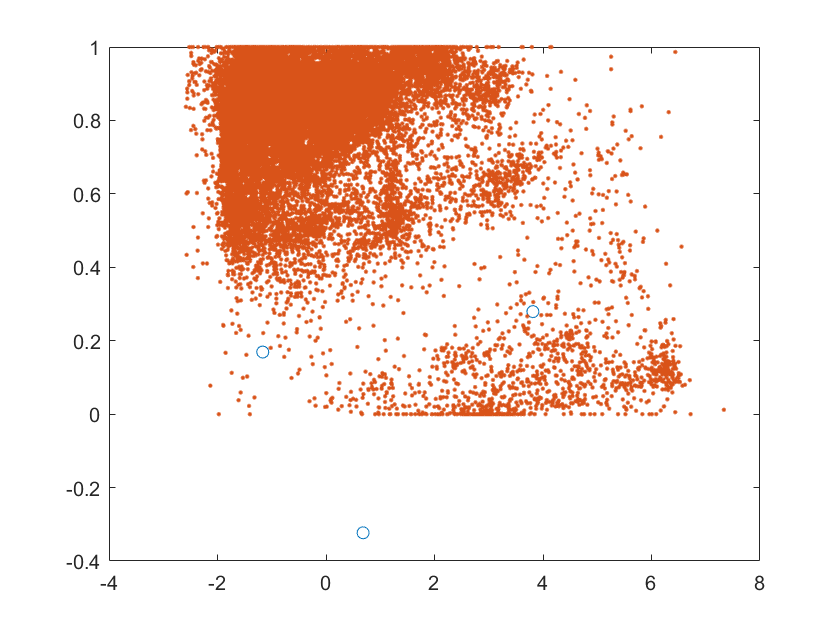

figure;
plot(Centroids(:,1),Centroids(:,2),'o'); hold on;
plot(x_ts_pc(:,1),x_ts_half(:,2),'.'); hold off;

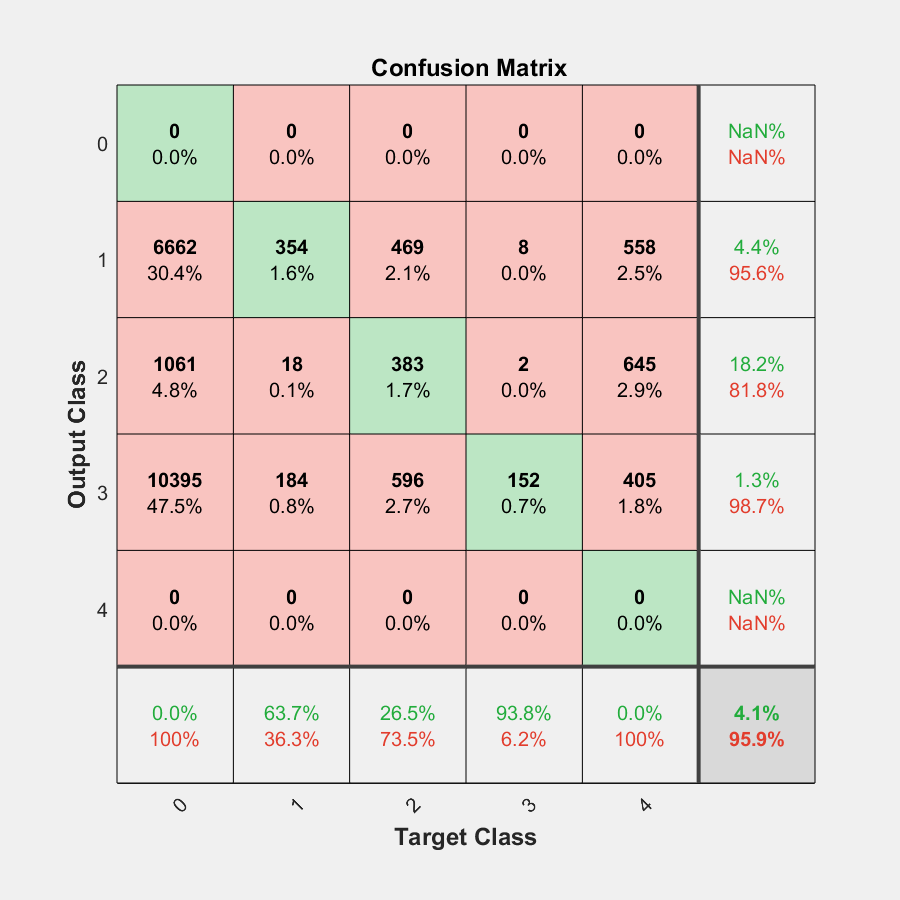

figure;

plotconfusion(categorical(y_ts'),categorical(prediction'));

unique(prediction)

ans =      1
     2
     3


d). Calculate the precision, recall and accuracy of each class and finally calculate the global F1-Score using the mean.

Since the previous classifier is not doing good I will proceed with a KNN model to predict the class that i have trained.

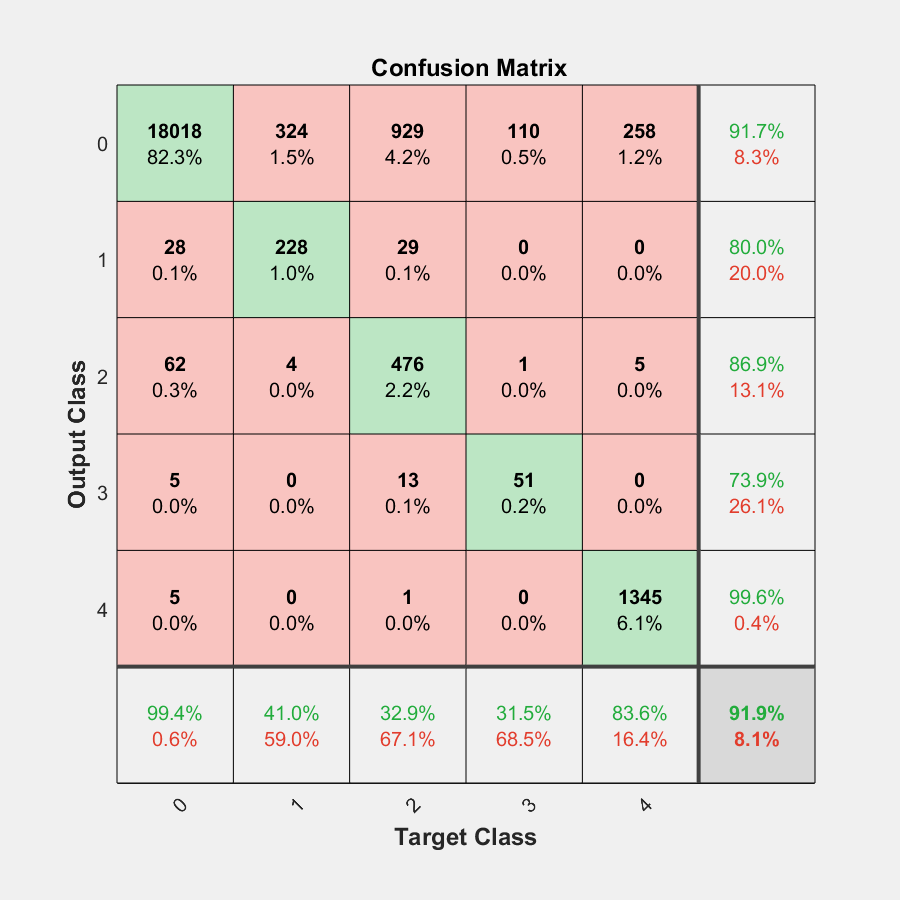

load('trainedModel.mat');
second_prediction = trainedModel.predictFcn(x_ts_pc);
plotconfusion(categorical(y_ts'),categorical(second_prediction'));

confusion = confusionmat(categorical(second_prediction'),categorical(y_ts'));
precision = diag(confusion)./sum(confusion,2);
recall = diag(confusion)./sum(confusion,1)';
f1Scores = 2*(precision.*recall)./(precision+recall);
meanF1 = mean(f1Scores)

meanF1 = 0.6648